
cd("/Users/yuqingdai/Documents/GitHub/HIVintern2022Summer/Old Paper/MATLAB/profile_likelihood")

data = readtable('../../data/data1/logvRNA.csv');
patients = unique(data.patient,'stable');

results = readtable('../new_work/results.csv');
[mn, idx] = min(results.J);
x0 = table2array(results(idx,2:end));

i = 1;
sub_data = data(data.patient == string(patients(i)),:);
dpi = sub_data.dpi;
y = sub_data.log_vRNA;

lsqnonlin: [https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_lsqnonlin_1](https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_lsqnonlin_1)


$$\min_x \;||f\left(x\right)||^2$$


cd("/Users/yuqingdai/Documents/MATLAB")

options = optimoptions(@lsqnonlin,'MaxIterations', 500);

fun = @(params) pred(params,dpi) - y;
[x,resnorm] = lsqnonlin(fun,x0,zeros(size(x0)),[],options);


Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


x_error = resnorm/size(y,1)

x_error = 0.0042

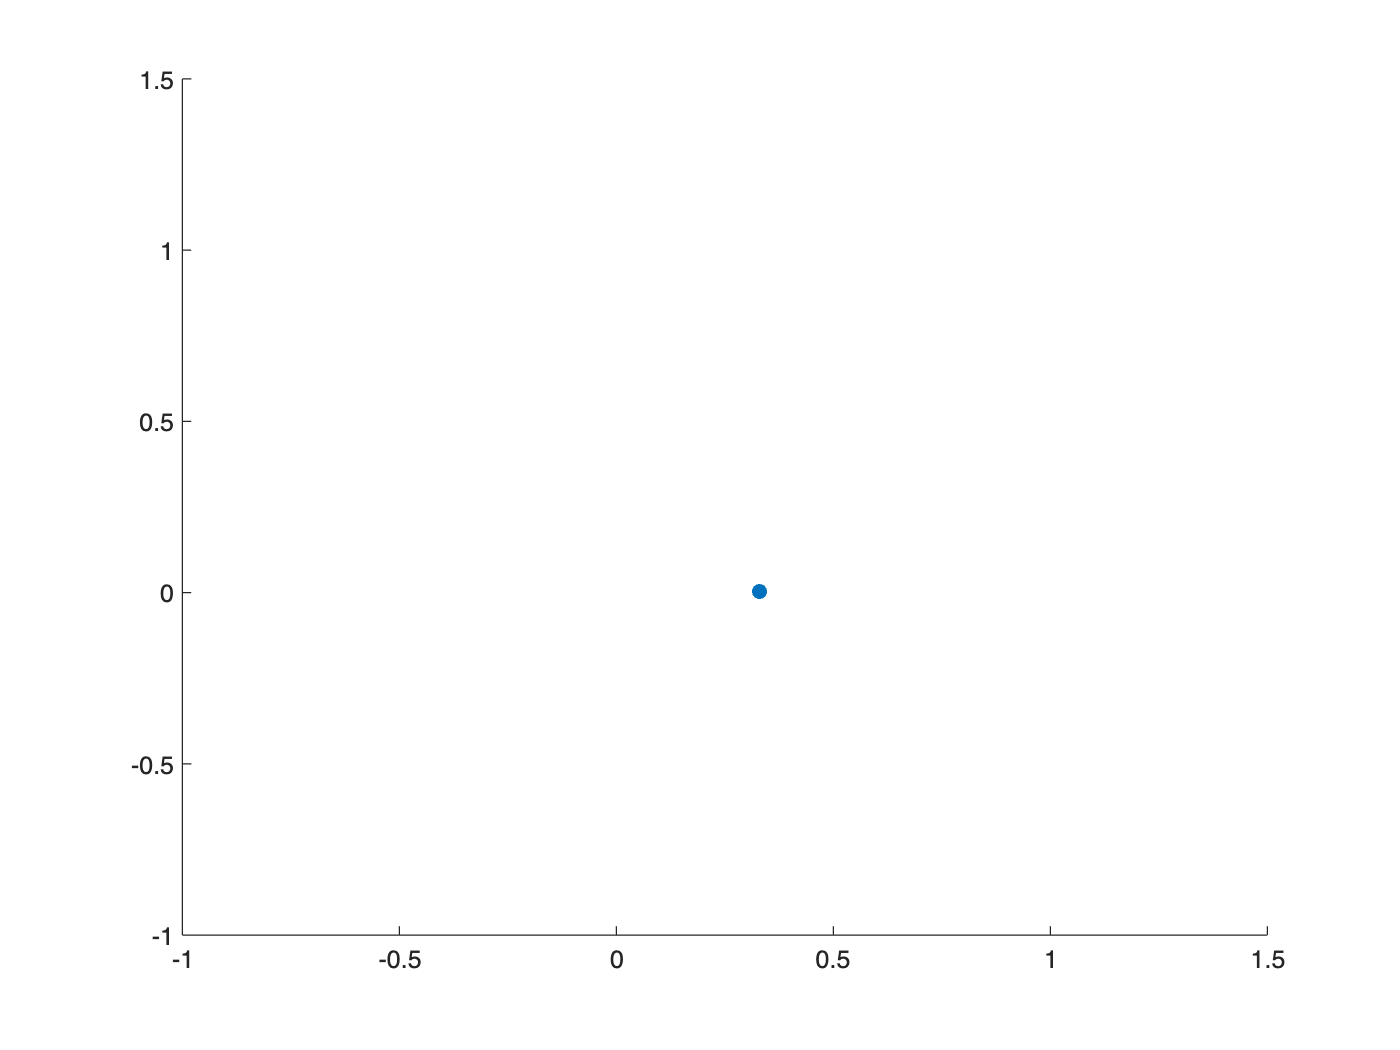

% J(x0,dpi,y)
scatter(x(3),x_error,'filled')
hold on 

xx = x;
num_samples = 20;
num_params = size(xx,2);

lb = 0.8 * xx;
up = 1.2 * xx;

sampled_params = zeros(num_params, num_samples);
for i = 1:num_params
    sampled_params(i,:) = linspace(lb(i),up(i),num_samples);
end

LSE = zeros(num_params,num_samples);


cd("/Users/yuqingdai/Documents/MATLAB")
num_params = 3;

options = optimoptions(@lsqnonlin,'MaxIterations', 500);
for ip = 3:num_params
    for is = 1:num_samples
        fprintf("Iteration %d\n",  ip*is);
        fp = sampled_params(ip,is);
        ic = [xx(1:ip-1) xx(ip+1:end)];

        fun = @(r) pred([r(1:ip-1) fp r(ip:end)],dpi) - y;
        [x,resnorm] = lsqnonlin(fun,ic,zeros(size(ic)),[],options);
        disp(resnorm/size(y,1))
        LSE(ip,is) = resnorm/size(y,1);
    end
end 

Iteration 3



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0047



Iteration 6



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0045



Iteration 9



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 12



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 15



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 18



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 21



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 24



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 27



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 30



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 33



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 36



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 39



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 42



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0042



Iteration 45



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 48



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 51



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0043



Iteration 54



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0044



Iteration 57



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0044



Iteration 60



Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


    0.0045



p1 = sampled_params(3,:);
a1 = LSE(3,:)

a1 =     0.0047    0.0045    0.0043    0.0043    0.0042    0.0042    0.0042    0.0042    0.0043    0.0043    0.0042    0.0042    0.0042    0.0042    0.0043    0.0043    0.0043    0.0044    0.0044    0.0045


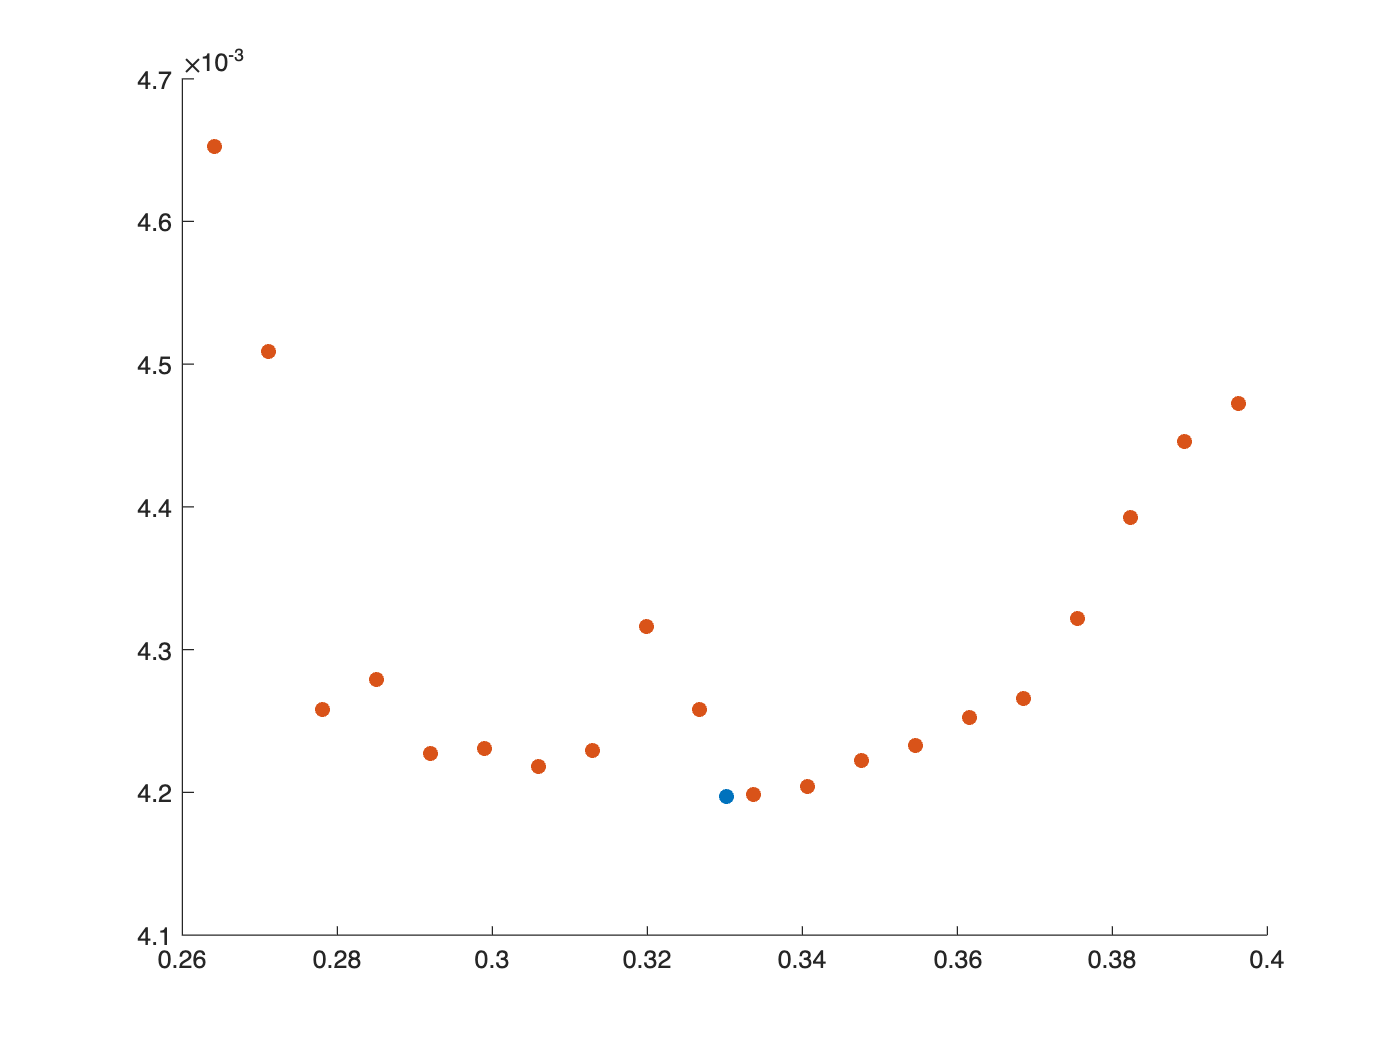

scatter(p1(a1>0),a1(a1>0),'filled')
hold off

% The decay function

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end

% % using viral dynamic model to predict V
% function out = pred(params,dpi)
%     h = 0.01;
%     ti = 0:h:dpi(end);
%     init = [10^4 0 10^-3];
%     b0 = params(1);
%     bi = params(2);
%     k = params(3);
%     dlt = params(4);
%     p = params(5);
%     d = params(6);
%     tau = params(7);
% 
%     f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
%             b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
%             p*x(2)-23*x(3) ];    
% 
%     [t,xa] = ode45(f,ti,init);
%     V = xa(:,3);
%     out = log10(V(dpi/h+1));
% end


% using viral dynamic model to predict V
function out = pred(params,dpi)
    h = 0.01;
    ti = 0:h:dpi(end);
    init = [10^4 0 10^-3];
    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);

    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    V = xa(:,3);
    try
        out = log10(V(dpi/h+1));
    catch 
        out = zeros(size(dpi));
    end
end

%% least-sqaured error
function out=J(params,dpi,y)
    y_hat = pred(params,dpi);
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

% %% least-sqaured error
% function out=J(params,dpi,y)
%     h = 0.01;
%     ti = 0:h:dpi(end);
%     V = pred(ti,params);
% 
%     y_hat = log10(V(dpi/h+1));
%     out =  1/size(y,1) *sum((y-y_hat).^2);
% end 

%% fix the fp paramter, using fminsearch to optimize others parameters
function [x,fval]=best_param(ic,fp,ip,dpi,y)
    % fp, ip
%     options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7); %,'MaxFunEvals', 5000,'MaxIter', 5000);
    JJ = @(params) J([params(1:ip-1) fp params(ip:end)], dpi,y);
    [x,fval] = fminsearch(JJ,ic); %,options);
end